# Energy Conservation

Here I compute the energy for the default boundary conditions and default parameters set in the wave program. The energy for this simulation should most definately not be conserverd, but the l2 norm between this energy and all simulations should be on the order of machine precision if things are done properly.


T1 = load('clock_time1.out')

T1 = 11439036

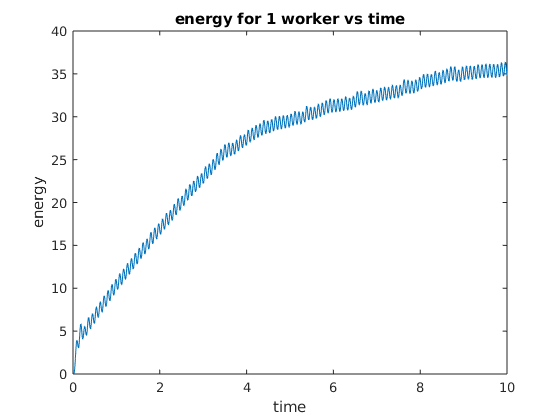

energy1 = load("energy1.out");
time1 = load('time1.out');
figure
plot(time1,energy1)
title('energy for 1 worker vs time')
xlabel('time')
ylabel('energy')

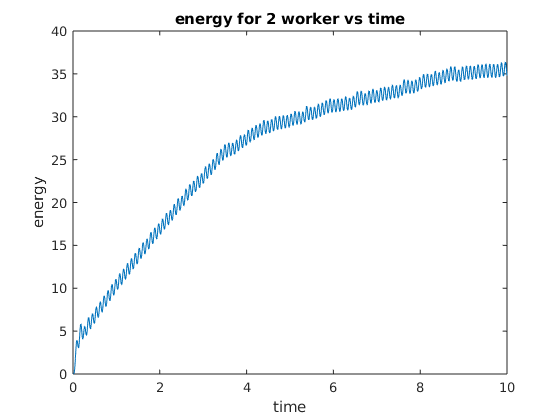

energy2 = load("energy.out");
time1 = load('time1.out');
figure
plot(time1,energy2)
title('energy for 2 worker vs time')
xlabel('time')
ylabel('energy')

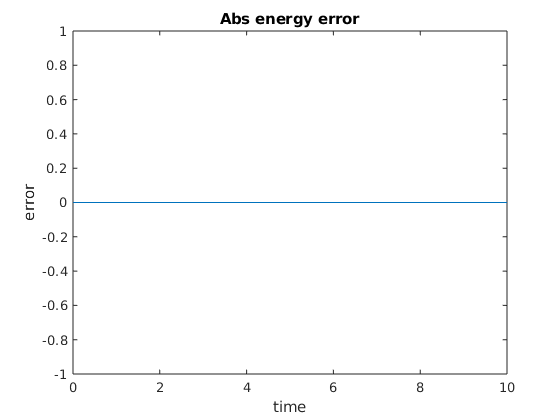

figure
plot(time1,abs(energy2-energy1))
title('Abs energy error')
xlabel('time')
ylabel('error')